# RSC

26/06/2024 attualmente il codice crea il grafo con l'algoritmo RSC, quindi non c'è bisogno di creare un percorso più smooth.

come ho fatto in aereo gia mi risolve un po i conflitti da controllare!!!

Da controllare:

- va aggiunto il controllo che il punto finale non deve coincidere sulle linee di altri punti (per farlo uso la matrice di occupazione, in cui andandola a definire tutti 1 lungo le curve poi dò la condizione che il punto finale dell'arco non deve essere 1, quindi non puo coincidere con una curva generata in precedenza); FATTO (in modo che il punto finale non coincida con la matrice di occupazione quindi finisca con un qualsiasi arco o linea creata in precedenza)

- matrice di adiacenza; in quanto il bfs lavora con la matrice di adiacenza, la quale definisce i nodi collegati, quindi va creata in questo senso; FATTO

- di conseguenza va definita la matrice di occupazione in cui per evitare che più punto coincidano, creo questa matrice di occupazione in cui una volta che il punto viene creato la matrice assume valore 1 in quella posizione; FATTO

- BFS, provare il BFS applicato nel file PRM_BFS_SMOOTH_FINAL qui. FATTO

va implementata questa funzione: findPathBFS(adjacency_matrix, samplePoints, Qs, Qg), gli input:

- la matrice di adiacenza va ricalcolata(va calcolato prima il vettore dei punti poi la matrice di adiacenza);

- va definito un vettore che salva tutti i punti;

- Qs lo abbiamo;

- Qg bisogna trovarlo e quindi definirlo. FATTO

clear all; clc; close all;

% Definizione dei parametri globali
global lunghezza_passo raggio_curva num_iterazioni points contatore occupancy_matrix map samplePoints connessioni

samplePoints = [];
connessioni = [];

% Load map from a .mat file
data = load('map_straight_with_roundabout.mat');
% data = load('test/Files_mat/maps_5_1.mat');  % Sostituisci 'nome_file_mappa.mat' con il tuo percorso e nome del file

% Check available fields in 'data' structure
disp(fieldnames(data));

    {'map_straight_with_roundabout'}




% Extract map from data structure
map = data.map_straight_with_roundabout';
% map = data.invertedImage;

% Definizione dei parametri
lunghezza_passo = 20; % Lunghezza del passo in avanti
raggio_curva = 15; % Raggio di curvatura per le curve a destra e sinistra
num_iterazioni = 20; % Numero di iterazioni

% Punto iniziale
Qs = [50, 40];
Qg = [415, 35];

% Inizializzazione del vettore per i punti
points = zeros(((num_iterazioni + 1)^3), 2);
points(1, :) = Qs;

% Inizializzazione della matrice di adiacenza
occupancy_matrix = zeros(size(map));
occupancy_matrix(Qs(1), Qs(2)) = 1;  % Segna il punto iniziale come visitato

occupancy_matrix(map == 0) = 1; % Marca le celle con ostacoli come visitate

% Contatore dei points
contatore = 1;

% Coda per i points da esplorare
queue = [Qs, 0, 1]; % [x, y, angolo, iterazione]

% Plot initialization
figure;
imshow(map');
hold on;
% Plotting the start and goal points on the map
plot(Qs(1), Qs(2), 'ro', 'MarkerSize', 7, 'LineWidth', 1.5);                      % Start point (red)
plot(Qg(1), Qg(2), 'go', 'MarkerSize', 7, 'LineWidth', 1.5);                      % Goal point (blue)

% Avvio della ricorsione dal punto iniziale
while ~isempty(queue)
    % Estrai il punto corrente dalla coda
    punto_corrente = queue(1, 1:2);
    angolo_corrente = queue(1, 3);
    iterazione = queue(1, 4);
    queue(1, :) = [];  % Rimuovi l'elemento dalla coda

    % Calcola i nuovi points e aggiungili alla coda se non visitati
    new_points = calculate_points(punto_corrente, angolo_corrente, iterazione);
    queue = [queue; new_points];  % Aggiungi i nuovi points alla coda
end

% Aggiunta delle annotazioni finali
title('Primitive Reed-Sheep Curves Iterative');
xlabel('X');
ylabel('Y');
%legend('Linee in avanti', 'points successivi', 'Curve a destra', 'Curve a sinistra');
axis equal;
grid on;

samplePoints = [Qs; samplePoints];

adjacency_matrix = create_adjacency_matrix(samplePoints, connessioni);

Find the path using BFS

[parent, current] = findPathBFS(adjacency_matrix, samplePoints, Qs, Qg);

Reconstructs the previously obtained path plotting it

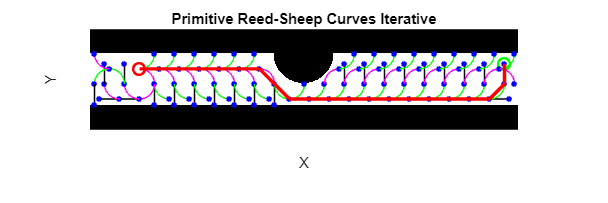

optimal_path = reconstructPath(parent, current, samplePoints);

% Funzione per calcolare i punti

function new_points = calculate_points(punto_corrente, angolo_corrente, iterazione)
    % Dichiarazione delle variabili globali
    global lunghezza_passo raggio_curva num_iterazioni points contatore occupancy_matrix samplePoints connessioni
    
    % Inizializzazione dei nuovi points
    new_points = [];

    % Condizione di terminazione della ricorsione
    if iterazione > num_iterazioni
        return;
    end

    % Calcolo del punto successivo in avanti
    punto_avanti = round(punto_corrente + lunghezza_passo * [cos(angolo_corrente), sin(angolo_corrente)]);
    punto_finale_avanti = punto_avanti;

    % Centro della circonferenza per la curva a destra
    centro_destra = punto_corrente + raggio_curva * [cos(angolo_corrente - pi/2), sin(angolo_corrente - pi/2)];

    % Centro della circonferenza per la curva a sinistra
    centro_sinistra = punto_corrente + raggio_curva * [cos(angolo_corrente + pi/2), sin(angolo_corrente + pi/2)];

    % Angoli per generare i quarti di cerchio
    theta_destra = linspace(angolo_corrente + pi/2, angolo_corrente, 100);
    theta_sinistra = linspace(angolo_corrente - pi/2, angolo_corrente, 100);

    x_destra = centro_destra(1) + raggio_curva * cos(theta_destra);
    y_destra = centro_destra(2) + raggio_curva * sin(theta_destra);
    punto_finale_destra = round([x_destra(end), y_destra(end)]);

    x_sinistra = centro_sinistra(1) + raggio_curva * cos(theta_sinistra);
    y_sinistra = centro_sinistra(2) + raggio_curva * sin(theta_sinistra);
    punto_finale_sinistra = round([x_sinistra(end), y_sinistra(end)]);

    % Aggiunta dei points e delle curve al plot solo se non coincidono con points precedenti
    hold on;

    if is_within_bounds(punto_finale_avanti) && ~is_point_visited(punto_finale_avanti)
        x_points = round(linspace(punto_corrente(1), punto_finale_avanti(1), 300));
        y_points = round(linspace(punto_corrente(2), punto_finale_avanti(2), 300));
        if ~is_collision_avanti(punto_corrente, punto_finale_avanti)
            contatore = contatore + 1;
            points(contatore, :) = punto_finale_avanti;
            samplePoints = [samplePoints; punto_finale_avanti];  % Aggiungi il nuovo punto alla matrice "samplePoints"
            occupancy_matrix(x_points, y_points) = 1;
            % occupancy_matrix(punto_finale_avanti(1), punto_finale_avanti(2)) = 1;  % Marca il punto come visitato
            plot([punto_corrente(1), punto_finale_avanti(1)], [punto_corrente(2), punto_finale_avanti(2)], 'k-', 'LineWidth', 0.5);
            plot(punto_finale_avanti(1), punto_finale_avanti(2), 'b.', 'MarkerSize', 10);
            new_points = [new_points; punto_finale_avanti, angolo_corrente, iterazione + 1];  % Aggiungi ai nuovi points
            connessioni = [connessioni; punto_corrente, punto_finale_avanti];  % Aggiungi la connessione
        end
    end

    if is_within_bounds(punto_finale_destra) && ~is_point_visited(punto_finale_destra)
        if ~is_collision_curve(x_destra, y_destra)
            contatore = contatore + 1;
            points(contatore, :) = punto_finale_destra;
            samplePoints = [samplePoints; punto_finale_destra];  % Aggiungi il nuovo punto alla matrice "samplePoints"
            occupancy_matrix(round(x_destra), round(y_destra)) = 1;
            %occupancy_matrix(punto_finale_destra(1), punto_finale_destra(2)) = 1;  % Marca il punto come visitato
            plot(x_destra, y_destra, 'g', 'LineWidth', 0.5);
            plot(x_destra(end), y_destra(end), 'b.', 'MarkerSize', 10);
            new_points = [new_points; punto_finale_destra, angolo_corrente - pi/2, iterazione + 1];  % Aggiungi ai nuovi points
            connessioni = [connessioni; punto_corrente, punto_finale_destra];  % Aggiungi la connessione
        end
    end

    if is_within_bounds(punto_finale_sinistra) && ~is_point_visited(punto_finale_sinistra)
        if ~is_collision_curve(x_sinistra, y_sinistra) 
            contatore = contatore + 1;
            points(contatore, :) = punto_finale_sinistra;
            samplePoints = [samplePoints; punto_finale_sinistra];  % Aggiungi il nuovo punto alla matrice "samplePoints"
            occupancy_matrix(round(x_sinistra), round(y_sinistra)) = 1;
            %occupancy_matrix(punto_finale_sinistra(1), punto_finale_sinistra(2)) = 1;  % Marca il punto come visitato
            plot(x_sinistra, y_sinistra, 'm', 'LineWidth', 0.5);
            plot(x_sinistra(end), y_sinistra(end), 'b.', 'MarkerSize', 10);
            new_points = [new_points; punto_finale_sinistra, angolo_corrente + pi/2, iterazione + 1];  % Aggiungi ai nuovi points
            connessioni = [connessioni; punto_corrente, punto_finale_sinistra];  % Aggiungi la connessione
        end
    end
end

% Funzione per verificare se un punto è già stato visitato
function visited = is_point_visited(punto)
    global occupancy_matrix
    visited = false;
    if occupancy_matrix(punto(1), punto(2)) == 1
        visited = true;
    end
end

% Funzione per verificare se un punto è all'interno dei limiti della matrice
function within_bounds = is_within_bounds(punto)
    global occupancy_matrix
    within_bounds = punto(1) > 0 && punto(2) > 0 && punto(1) <= size(occupancy_matrix, 1) && punto(2) <= size(occupancy_matrix, 2);
end

% Funzione per verificare se un punto è all'interno dei limiti della matrice
function collision_avanti = is_collision_avanti(punto_corrente, punto_finale_avanti)
    global map

    collision_avanti = false;
    % disp(collision_avanti);
    % Calcola i points equidistanti tra p_start e p_end
    x_points = round(linspace(punto_corrente(1), punto_finale_avanti(1), 300));
    y_points = round(linspace(punto_corrente(2), punto_finale_avanti(2), 300));
    for i = 2:(length(x_points)-1)
        if map(x_points(i), y_points(i)) == 0
            collision_avanti = true;
            break
        end
    end
    % disp(collision_avanti);
end

% Funzione per verificare se un punto è all'interno dei limiti della matrice
function collision_curve = is_collision_curve(x, y)
    global map

    collision_curve = false;
    % disp(collision_curve);
    for i = 2:(length(x)-1)
        if map(round(x(i)), round(y(i))) == 0
            collision_curve = true;
            break
        end
    end
    % disp(collision_curve);
end

function adjacency_matrix = create_adjacency_matrix(nodi, connessioni)
    num_nodi = size(nodi, 1);
    adjacency_matrix = zeros(num_nodi);

    for i = 1:size(connessioni, 1)
        punto1 = connessioni(i, 1:2);
        punto2 = connessioni(i, 3:4);
        
        idx1 = find(ismember(nodi, punto1, 'rows'));
        idx2 = find(ismember(nodi, punto2, 'rows'));
        
        if ~isempty(idx1) && ~isempty(idx2)
            adjacency_matrix(idx1, idx2) = 1;
            adjacency_matrix(idx2, idx1) = 1;  % Assumendo che il grafo sia non diretto
        end
    end
end


Find the path using BFS

% Function to find path using BFS
function [parent, current] = findPathBFS(adjacency_matrix, samplePoints, Qs, Qg)
    nodes = samplePoints;
    num_samples = size(nodes, 1);

    % Find indices of start and goal nodes in nodes array
    [~, Qstart_index] = min(pdist2(nodes, Qs));
    [~, Qgoal_index] = min(pdist2(nodes, Qg));

    % BFS initialization
    queue = Qstart_index;              % Start with the index of the start node
    parent = zeros(1, num_samples);
    visited = false(1, num_samples);
    visited(Qstart_index) = true;      % Mark start node as visited

    % BFS search
    while ~isempty(queue)
        current = queue(1);
        queue(1) = [];
        
        if current == Qgoal_index
            % Reconstruct the path from goal to start
            % Interpolate the path using splines
            % Both are done in the main
            return;
        end
        
        % Explore neighbors (nodes connected to current)
        neighbors = find(adjacency_matrix(current,:) == 1);
        for i = 1:length(neighbors)
            if ~visited(neighbors(i))
                visited(neighbors(i)) = true;
                parent(neighbors(i)) = current;
                queue(end+1) = neighbors(i);
            end
        end
    end
end

Reconstructs the previously obtained path plotting it

function path = reconstructPath(parent, goal, nodes)
    path = [];
    current = goal;
    while current ~= 0
        path = [current, path];
        current = parent(current);
    end
    plotPath(path, nodes, 'r');
end

function plotPath(path, nodes, color)
    for i = 1:length(path)-1
        line( [nodes(path(i),1), nodes(path(i+1),1)], [nodes(path(i),2), nodes(path(i+1),2)], 'Color', color, 'LineWidth', 2);
    end
end